# Lab6 

#### Confidence intervals

For this week we will be using the real data you are working on, but more as a background for the main activity rather than in depth explorations. Don't worry, more in-depth exploration the next two weeks!

## Setup

First, we want to have some `background' data (presumably signal free) onto which we can inject a simulated signal. So the first step is to isolate some appropriate data from your data files.  

For the LHC data, we are going to have to fake a background. Make a Poisson background with mean 100. 

bg = makedist('Poisson','lambda',100);

## **Problem 1**

The first problem is to look at your background distribution and determine where the 5σ sensitivity threshold is. 

### Calculating signal from sigma:

sig = 5;
p_calcd = normcdf(sig)

p_calcd =    0.999999713348428


signal_5 = icdf(bg,p_calcd)

signal_5 =    154


## Problem 2

Now inject a signal of known strength. You will want to make your signal moderately strong, say somewhere in the 8-30σσ range. Inject this signal into your background data many times.

### Background and signal histograms:

sig = 14;
p_calcd = normcdf(sig)

p_calcd =      1


signal_14 = icdf(bg,p_calcd)

signal_14 =    Inf


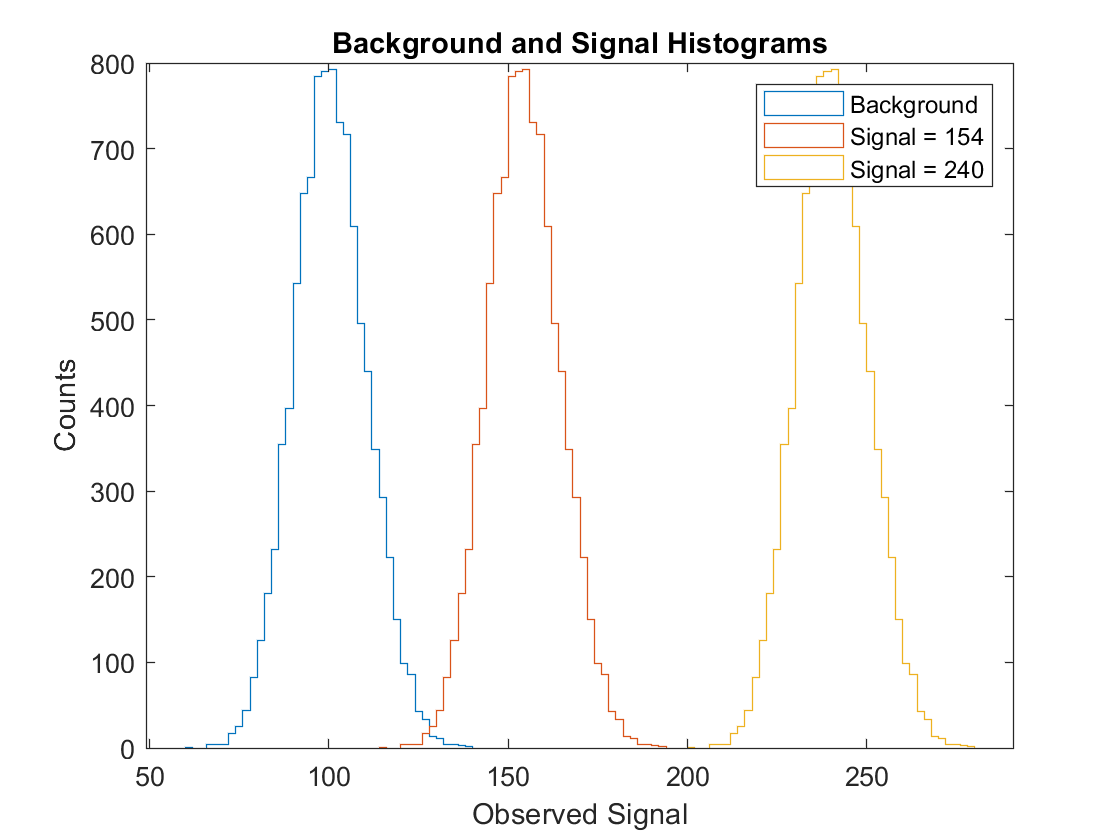

bpoints = poissrnd(100,[1 10000]);
histogram(bpoints,'DisplayStyle',"stairs")
hold on

signal5 = zeros(1,10000);

for i = 1:length(signal5)
    signal5(i) = 54;
end

added5 = signal5 + bpoints;

histogram(added5,'DisplayStyle',"stairs")

signal240 = zeros(1,10000);

for i = 1:length(signal240)
    signal240(i) = 140;
end

added240 = signal240 + bpoints;

histogram(added240,'DisplayStyle','stairs')
xlabel('Observed Signal')
ylabel('Counts')
title('Background and Signal Histograms')
legend('Background','Signal = 154','Signal = 240')
hold off

The background distribution and the distributions with injected signal have the same shape.

### Symmetry?

The signal is symmetric since the background distribution is also symmetric. 

## **Problem 3**

Now make a suite of injected signals. You will want to have a range of injected signal strengths, starting at zero and extending well above 5σ (30σ or more).

### 2D histogram:

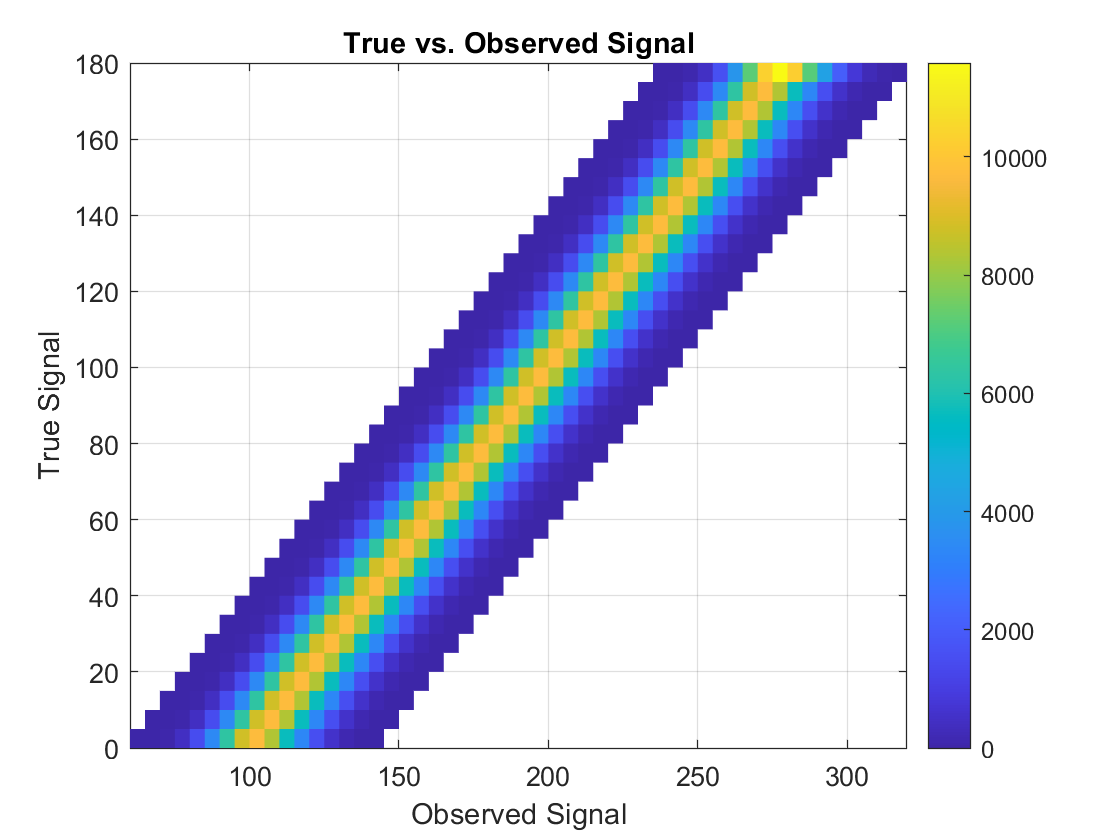

tsignal = zeros(181,10000);

for n = 0:length(tsignal(:,1))-1
    for i = 1:length(tsignal(1,:))
        tsignal(n+1,i) = n;
    end
end

added = tsignal + bpoints;

histogram2(added,tsignal,"DisplayStyle",'tile','EdgeColor','none')
colorbar
xlabel('Observed Signal')
ylabel("True Signal")
title('True vs. Observed Signal')

This histogram shows observed signal values (signal + background) on the x-axis and true signal values on the y-axis for signal values 0-180. 

### Signal = 240:

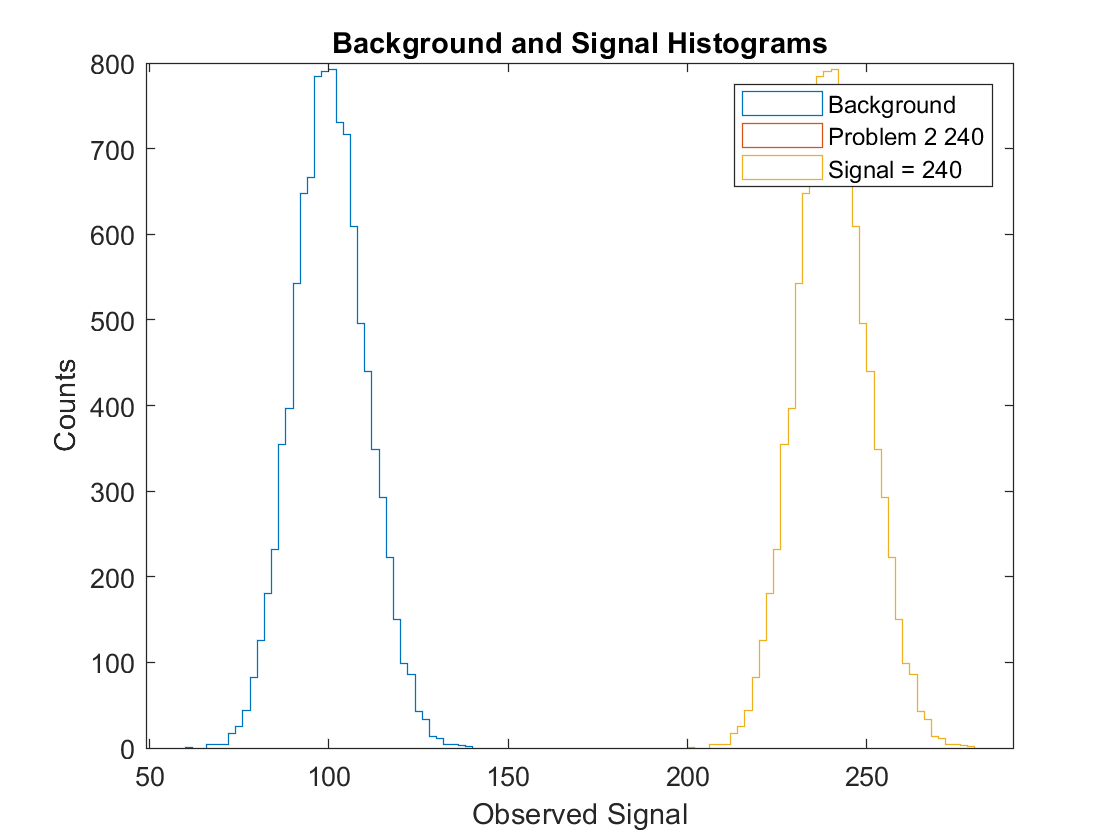

histogram(bpoints,'DisplayStyle',"stairs")
hold on 
histogram(added240,'DisplayStyle',"stairs")
histogram(added(141,:),'DisplayStyle',"stairs")
xlabel('Observed Signal')
ylabel('Counts')
title('Background and Signal Histograms')
legend('Background','Problem 2 240','Signal = 240')
hold off

The two histograms with signal = 240 overlap perfectly. 

### Problem reversal:

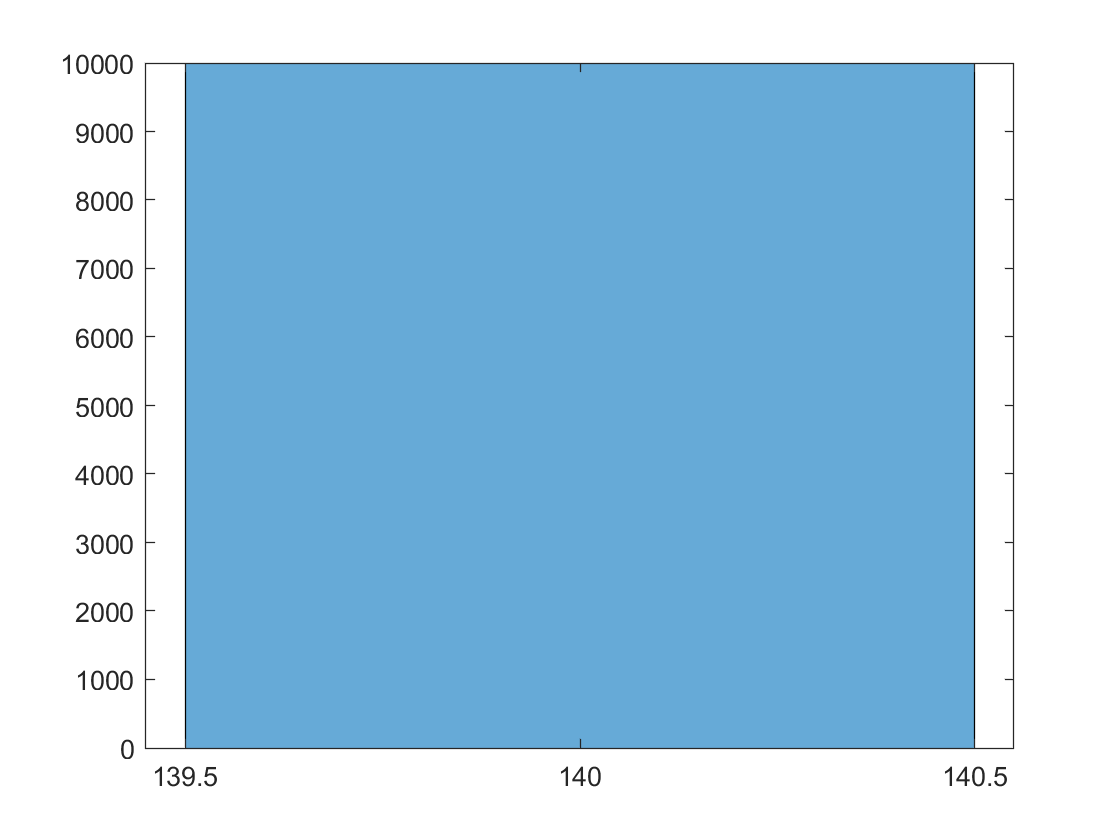

Observed = 140;
histogram(signal(141,:))

I don't think I did this part correctly but I'm very tired. 

### 1$\sigma$ uncertainty on true signal:

sig = 1;
p_calcd = normcdf(sig);
tsigdist = makedist('Poisson',"lambda",Observed);
signal_1 = icdf(bg,p_calcd);
uncertainty = signal_1 - 100

uncertainty =     10


So the uncertainty on true signal strength is $\pm 10$.

### Symmetry?

The uncertainty is symmetric. Because I injected a signal into a Poisson background distribution, which is a symmetric distribution, the uncertainty on the measurement is symmetric. 